Companion software for "Volker Ziemann, *Physics and Finance, Springer, 2021*" ([https://link.springer.com/book/10.1007/978-3-030-63643-2](https://link.springer.com/book/10.1007/978-3-030-63643-2))

# Log-normal explorer (Section 4.5)

Volker Ziemann, 211115, CC-BY-SA-4.0

In this example we display the log-normal distribution function fro Equation 4.32 and provide an easy-to-change interface using sliders to play wit hthe input parameters. 

K=2;        % strike price
sigma=0.3;    % volatility/sqrt(year)
rho=0.1;     % annual return/year
t=1;       % time until maturity

We now calculate $\hat\rho=\rho-\sigma^2/2$ and define the scale of the horzontal axis `s`, as well as $\Psi(s) from Equation 4.32, plot the curve and annotate the axes.

rhat=rho-0.5*sigma^2;
s=0.01:0.01:3.5;
Psi1=lognorm(s,sigma,rhat,t); 
figure(1); clf
plot(s,Psi1,'k');
xlabel('Normalized share value S/S_0')
ylabel('Probability distribution dP/ds')

Finally we show the are under the curve where the stock value exceeds the strike price and calculate the fraction of that, which is equal to the probability of exceeding the strike price after the end of the time horizon---at maturity.

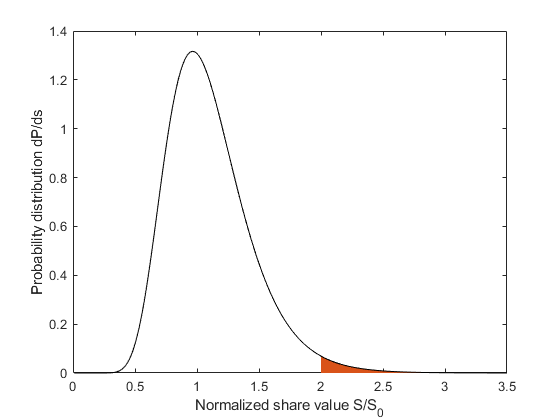

hold on
s2=K:0.01:3.5;
q2=lognorm(s2,sigma,rhat,t);
area(s2,q2)

tail_probability=integral(@(s)lognorm(s,sigma,rhat,t),K,Inf)

tail_probability = 0.0167

Now play with the sliders and change the input parameters! Does the system behave the way you expect?

## Appendix

The function` lognorm()` returns the log-normal distribution function $\Psi$ from Equation 4.32. It receives the normalized share value $s=S/S_0$, the annual volatility $\sigma$, the annual growth rate $\rho$, and the time $t$ as input and returns $\Psi$.

function out=lognorm(s,sigma,rho,t)
exponent=((log(s)-rho.*t).^2)./(2*sigma^2.*t);
out=exp(-exponent)./(s.*sqrt(2*pi.*t.*sigma.^2));
end